load("design_points_data.mat");

% Initialize arrays to store valid design points
valid_indices = [];  % To store [i, j, k, l]
valid_T9 = [];
valid_mgross = [];
valid_mbattery = [];

% Loop through all design points
for k = 1:size(V_cruise, 2)
    for i = 1:size(T9, 2)
        for j = 1:size(RPM, 2)
            for l = 1:size(thetatw, 2)
                if  mgross(i,j,k,l) > 1 && m_battery(i,j,k,l) < 30 && wing_b(i,j,k,l)<8
                    valid_indices = [valid_indices; i, j, k, l];
                    valid_T9 = [valid_T9; T9(i)/60];  % Convert to minutes
                    valid_mgross = [valid_mgross; O2(i,j,k,l)];
                    valid_mbattery = [valid_mbattery; m_battery(i,j,k,l)];
                end
            end
        end
    end
end

## 1 mgross vs mbattery vs T9 coloured RPM

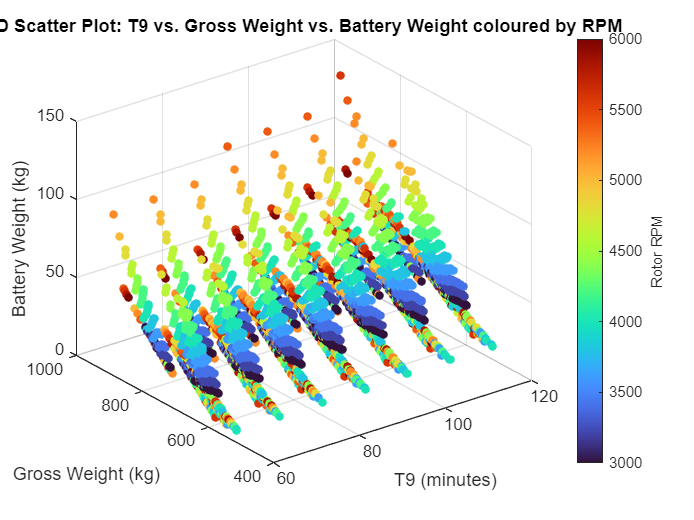

figure;
hold on;
grid on;

% Loop through all design points
for k = 1:size(V_cruise, 2)
    for i = 1:size(T9, 2)
        for j = 1:size(RPM, 2)
            for l = 1:size(thetatw, 2)
                if O2(i,j,k,l) > 0
                    % --- Customize here ---
                    markerSize = 26;                  % Larger markers
                    c = RPM(j);                       % Color by RPM
                    scatter3(T9(i)/60, O2(i,j,k,l), m_battery(i,j,k,l), ...
                           markerSize, c, 'filled');
                end
            end
        end
    end
end

% --- Color scheme & labels ---
colormap(turbo);              % color scheme
colorbar;
ylabel(colorbar, 'Rotor RPM');
clim([min(RPM) max(RPM)]); % Scale colors to RPM range

% --- Axis labels ---
xlabel('T9 (minutes)');
ylabel('Gross Weight (kg)');
zlabel('Battery Weight (kg)');
title('3D Scatter Plot: T9 vs. Gross Weight vs. Battery Weight coloured by RPM');
view(3); % 3D perspective

## 2 mgross vs mbattery vs T9 coloured V_cruise

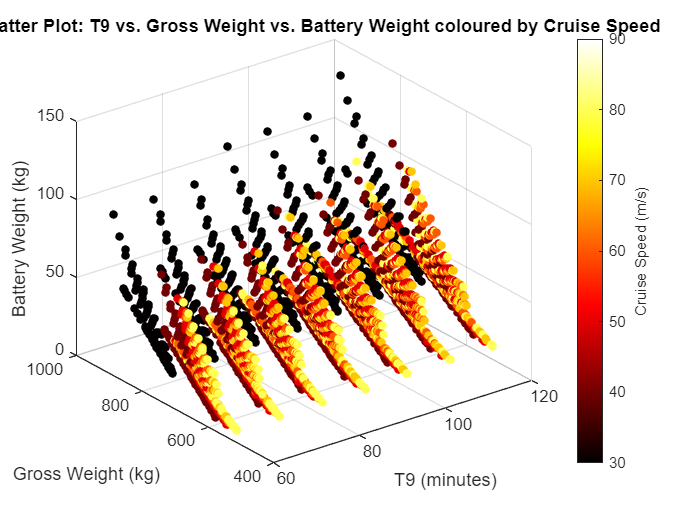

figure;
hold on;
grid on;

% Loop through all design points
for k = 1:size(V_cruise, 2)
    for i = 1:size(T9, 2)
        for j = 1:size(RPM, 2)
            for l = 1:size(thetatw, 2)
                if O2(i,j,k,l) > 0
                    % --- Customize here ---
                    markerSize = 26;                  % Larger markers
                    c = V_cruise(k);                       % Color by variable
                    scatter3(T9(i)/60, O2(i,j,k,l), m_battery(i,j,k,l), ...
                           markerSize, c, 'filled');
                end
            end
        end
    end
end

% --- Color scheme & labels ---
colormap("hot");              % color scheme
colorbar;
ylabel(colorbar, 'Cruise Speed (m/s)');
clim([min(V_cruise) 90]); % Scale colors to RPM range

% --- Axis labels ---
xlabel('T9 (minutes)');
ylabel('Gross Weight (kg)');
zlabel('Battery Weight (kg)');
title('3D Scatter Plot: T9 vs. Gross Weight vs. Battery Weight coloured by Cruise Speed');
view(3); % 3D perspective

## 3 mgross vs Wingspan vs T9 coloured thetatw

figure;
hold on;
grid on;

% Loop through all design points
for k = 1:size(V_cruise, 2)
    for i = 1:size(T9, 2)
        for j = 1:size(RPM, 2)
            for l = 1:size(thetatw, 2)
                if O2(i,j,k,l) > 0
                    % --- Customize here ---
                    markerSize = 26;                  % marker size
                    c = thetatw(l);                       % Color by variable
                    scatter3(T9(i)/60, O2(i,j,k,l), wing_b(i,j,k,l), ...
                           markerSize, c, 'filled');
                end
            end
        end
    end
end

% --- Color scheme & labels ---
colormap("copper");              % color scheme
colorbar;
ylabel(colorbar, 'Blade Twist Rate (degrees)');
clim([min(thetatw) max(thetatw)]); % Scale colors to RPM range

% --- Axis labels ---
xlabel('T9 (minutes)');
ylabel('Gross Weight (kg)');
zlabel('Battery Weight (kg)');
title('3D Scatter Plot: T9 vs. Gross Weight vs. Battery Weight coloured by Blade Twist Rate');
view(3); % 3D perspective

## 4 mgross vs mbattery vs T9 coloured thetatw

figure;
hold on;
grid on;

% Loop through all design points
for k = 1:size(V_cruise, 2)
    for i = 1:size(T9, 2)
        for j = 1:size(RPM, 2)
            for l = 1:size(thetatw, 2)
                if O2(i,j,k,l) > 0
                    % --- Customize here ---
                    markerSize = 26;                  % marker size
                    c = thetatw(l);                       % Color by variable
                    scatter3(T9(i)/60, O2(i,j,k,l), m_battery(i,j,k,l), ...
                           markerSize, c, 'filled');
                end
            end
        end
    end
end

% --- Color scheme & labels ---
colormap("copper");              % color scheme
colorbar;
ylabel(colorbar, 'Blade Twist Rate (degrees)');
clim([min(thetatw) max(thetatw)]); % Scale colors to RPM range

% --- Axis labels ---
xlabel('T9 (minutes)');
ylabel('Gross Weight (kg)');
zlabel('Battery Weight (kg)');
title('3D Scatter Plot: T9 vs. Gross Weight vs. Battery Weight coloured by Blade Twist Rate');
view(3); % 3D perspective

## 5 mgross vs T9 vs V_cruise coloured thetatw

figure;
hold on;
grid on;

% Loop through all design points
for k = 1:size(V_cruise, 2)
    for i = 1:size(T9, 2)
        for j = 1:size(RPM, 2)
            for l = 1:size(thetatw, 2)
                if O2(i,j,k,l) > 0 && m_battery(i,j,k,l)< 30 && wing_b(i,j,k,l)< 8
                    % --- Customize here ---
                    markerSize = 26;                  % marker size
                    c = thetatw(l);                       % Color by variable
                    scatter3(T9(i)/60, V_cruise(k), O2(i,j,k,l), ...
                           markerSize, c, 'filled');
                end
            end
        end
    end
end

% --- Color scheme & labels ---
colormap("jet");              % color scheme
colorbar;
ylabel(colorbar, 'Blade Twist Rate (degrees)');
clim([min(thetatw) max(thetatw)]); % Scale colors to RPM range

% --- Axis labels ---
xlabel('T9 (minutes)');
ylabel('Cruise Speed (m/s)');
zlabel('Gross Weight (kg)');
title('3D Scatter Plot: T9 vs. Cruise Speed vs. Gross Weight coloured by Blade Twist Rate');
view(3); % 3D perspective

## 6 mgross vs T9 vs V_cruise coloured mfuel_cell

figure;
hold on;
grid on;

% Loop through all design points
for k = 1:size(V_cruise, 2)
    for i = 1:size(T9, 2)
        for j = 1:size(RPM, 2)
            for l = 1:size(thetatw, 2)
                if O2(i,j,k,l) > 0 && m_battery(i,j,k,l)< 30 && wing_b(i,j,k,l)< 8
                    % --- Customize here ---
                    markerSize = 26;                  % marker size
                    c = mfuel_cell(i,j,k,l);                       % Color by variable
                    scatter3(T9(i)/60, V_cruise(k), O2(i,j,k,l), ...
                           markerSize, c, 'filled');
                end
            end
        end
    end
end

% --- Color scheme & labels ---
colormap("turbo");              % color scheme
colorbar;
ylabel(colorbar, 'Fuel System Weight (kg)');
clim([100 350]); % Scale colors to RPM range

% --- Axis labels ---
xlabel('T9 (minutes)');
ylabel('Cruise Speed (m/s)');
zlabel('Gross Weight (kg)');
title('3D Scatter Plot: T9 vs. Cruise Speed vs. Gross Weight coloured by Fuel System Weight');
view(3); % 3D perspective

## 7 mgross vs T9 vs V_cruise coloured Blade Loading

figure;
hold on;
grid on;

% Loop through all design points
for k = 1:size(V_cruise, 2)
    for i = 1:size(T9, 2)
        for j = 1:size(RPM, 2)
            for l = 1:size(thetatw, 2)
                if O2(i,j,k,l) > 0 && m_battery(i,j,k,l)< 30 && wing_b(i,j,k,l)< 8
                    % --- Customize here ---
                    markerSize = 26;                  % marker size
                    c = C_T(i,j,k,l)/solidity(i,j,k,l);                       % Color by variable
                    scatter3(T9(i)/60, V_cruise(k), O2(i,j,k,l), ...
                           markerSize, c, 'filled');
                end
            end
        end
    end
end

% --- Color scheme & labels ---
colormap("hot");              % color scheme
colorbar;
ylabel(colorbar, 'Blade Loading in Hover');
clim([min(C_T(:)/0.0637) 0.06]); % Scale colors to RPM range

% --- Axis labels ---
xlabel('T9 (minutes)');
ylabel('Cruise Speed (m/s)');
zlabel('Gross Weight (kg)');
title('3D Scatter Plot: T9 vs. Cruise Speed vs. Gross Weight coloured by Blade Loading');
view(3); % 3D perspective

## 8 theta tw vs RPM vs T9 coloured Blade Loading

figure;
hold on;
grid on;

% Loop through all design points
for k = 1:size(V_cruise, 2)
    for i = 1:size(T9, 2)
        for j = 1:size(RPM, 2)
            for l = 1:size(thetatw, 2)
                if O2(i,j,k,l) > 0 && m_battery(i,j,k,l)< 30 && wing_b(i,j,k,l)< 8
                    % --- Customize here ---
                    markerSize = 26;                  % marker size
                    c = C_T(i,j,k,l)/solidity(i,j,k,l);                       % Color by variable
                    scatter3(thetatw(l), RPM(j), T9(i)/60, ...
                           markerSize, c, 'filled');
                end
            end
        end
    end
end

% --- Color scheme & labels ---
colormap("hot");              % color scheme
colorbar;
ylabel(colorbar, 'Blade Loading in Hover');
clim([min(C_T(:)/0.0637) 0.06]); % Scale colors to RPM range

% --- Axis labels ---
xlabel('T9 (minutes)');
ylabel('Cruise Speed (m/s)');
zlabel('Gross Weight (kg)');
title('3D Scatter Plot: T9 vs. Cruise Speed vs. Gross Weight coloured by Blade Loading');
view(3); % 3D perspective